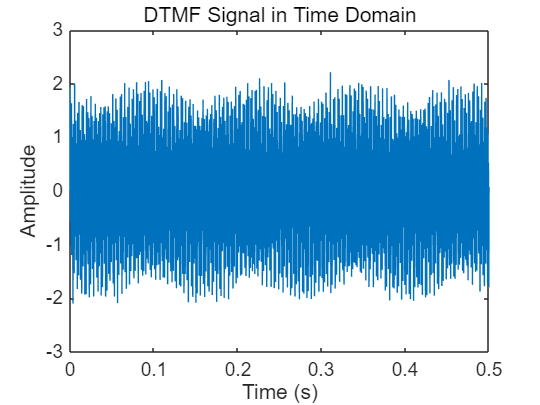

% DTMF 信号识别示例
clear; clc;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 输入可调
% 生成测试 DTMF 信号（例如按下 '5'）
[signal, fs] = generateSignal('5');
t = 0 : 1 / fs : 0.5; % 时间向量，持续 0.5 秒
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% 绘制时间域信号
figure;
plot(t, signal);
title('DTMF Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

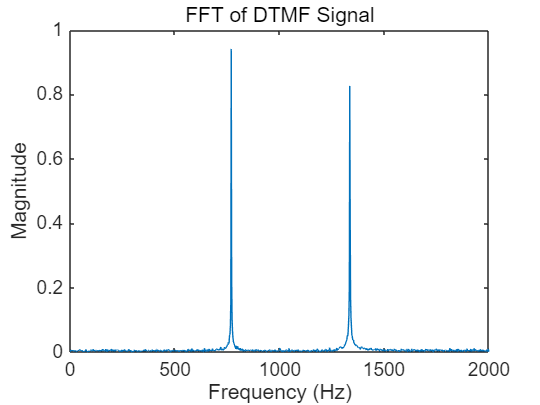


% 进行 FFT
N = length(signal);
Y = fft(signal);
P2 = abs(Y/N); % 双边振幅谱
P1 = P2(1 : floor(N / 2) + 1); % 单边振幅谱
P1(2 : end - 1) = 2 * P1(2 : end - 1); % 单边振幅谱修正
f = fs * (0 : floor(N/2)) / N; % 频率轴

% 绘制频域信号
figure;
plot(f, P1);
title('FFT of DTMF Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0, fs / 2]); % 限制到相关频率范围


directDetect(signal, fs)

ans = '5'